# Calculating the forces in rear suspension members

% Written by Seth Rigsby and Christina Lachapelle
% 1/19/2022

clear,clc, format shortG


## Part 1: Maximum Forces for each case (at contact patch)

% Car Parameters
m = 275;   % mass of car in kg
g = 9.81;    % graviational force
wheelbase = 1.544; %  center-center length between wheels [m]
l1 = wheelbase/1.5;   % distance from front tire to center of mass [m]
l2 = wheelbase - l1; % Cm to rear tire [m]
h_cm = .400;    % height of center of mass [m];
T = 1.200;    % track width [m]
tire_diameter = 20*25.4/1000; % out diameter of tire (not rim) [m];
wheel_offset = (40.6/2 + 3*25.4) /1000;    % Distance from the upright origin to the wheel contact patch [m]

% For all of this sections' calculations, it was assumed that positive x-direction
% was towards the front of the car, positive y direction was toward the
% center of the car from the left side, and positive z-direction is up. 

% Maximum static weight
W_static = (0.5*m*g) *(4.3*1.3); % weight of car to calculate force on one rear tire
Fx_static = 0;
Fy_static = 0;
Fz_static = (l1/wheelbase)*W_static;
Mx_static = 0;
My_static = 0;
Mz_static = 0;

% Maximum Braking Force
W_braking = g*m%*4.3

W_braking =        2697.8


Wr_braking = (l1/wheelbase) * W_braking;
friction_braking = 1.2;

F_braking = Wr_braking*friction_braking;
Delta_Wx_braking = F_braking*h_cm/wheelbase;
Wrr_braking = (Wr_braking-Delta_Wx_braking)/2;

Fx_braking = F_braking*1.2 % longitudinal force acting toward front of car

Fx_braking =        2589.8


Fy_braking = 0; 
Fz_braking = 1.3*Wrr_braking % vertical force acting upward

Fz_braking =         805.6


Mx_braking = 0;
My_braking = Fx_braking*(tire_diameter/2)  % Fx in x causes moment about y [N*mm]

My_braking =        657.82


Mz_braking = wheel_offset * Fx_braking     % SIMPLIFICATION - this is not accounting for -2deg camber

Mz_braking =        249.92



% Maximum Acceleration 
friction_acc = 1.5;
Fa = Fz_static * friction_acc/(1-h_cm*friction_acc/wheelbase)

Fa =         12333


Delta_Wx_acc = h_cm*Fa/wheelbase;

Fy_acc = 0;
Fz_acc = 1.3*(Fz_static + Delta_Wx_acc)/2 % force on the contact patch of one tire upward [N]

Fz_acc =        5344.2


Fx_acc = Fz_acc * 1.5 % longitudinal design force acting toward the back of the car at the center of the wheel

Fx_acc =        8016.3


Mx_acc = 0;
My_acc = 0;     % This would be nonzero but our max case is braking so doens't mattter
Mz_acc = 0;

% Maximum Cornering Case
W_cornering = m*g*2%4.3*

W_cornering =        5395.5


F_cornering = W_cornering*1.5 % 1.5 is the frictional coefficient

F_cornering =        8093.2



Delta_Wy_cornering = F_cornering*h_cm/T;

Fx_cornering = 0;
Fy_cornering = Fx_braking % acts toward the inside of the car at contact patch $$ ASSSUMING FRICTION-LIMITED AS IN BRAKING

Fy_cornering =        2589.8


Fz_cornering = Delta_Wy_cornering % acts upward at contact patch

Fz_cornering =        2697.8



Mx_cornering = Fy_cornering*(tire_diameter/2) % force in the y-z plane causes moment about x

Mx_cornering =        657.82


My_cornering = 0;
Mz_cornering = 0;

% Maximum forces occur during cornering and braking:
Fx = Fx_cornering+Fx_braking

Fx =        2589.8


Fy = Fy_braking+Fy_cornering

Fy =        2589.8


Fz = Fz_cornering+Fz_braking

Fz =        3503.3



% Maximum moments are caused by a cornering and braking scenario, so we add the two:
Mx = Mx_cornering + Mx_braking

Mx =        657.82


My = My_cornering + My_braking

My =        657.82


Mz = Mz_cornering + Mz_braking

Mz =        249.92


## Part 2: Definition of Nodes in 3 Dimensions

% This section uses the coordinate system defined in the paper, and assumes triangle IJK is ata 2.5 deg angle (s_ang) to the XY plane
camber_ang = -2;
r_l = 343/1000;
r_u = 274.4/1000;
r_ho = 72.77/1000;
r_w = wheel_offset; %40.6 mm;
r_h = 190.5/1000;    

s_l = 350.6/1000;    % SV lower A-A length
s_u = 280/1000;      % side view upper A-Arm length
s_h = 142.85/1000;   % Side view A-Arm normal distance
s_ang = 2.25;   % Side view A-arm angle 



cg_I = [-l2, (T/2 - r_l + r_w*sind(camber_ang)), -h_cm + tire_diameter/2 - r_h*cosd(camber_ang)/2]

cg_I =      -0.51467      0.25363     -0.24119


% I = [1280;130;0]';    % Front a-arm Bottom to Chassis
I = cg_I;
% J = [941;570;-150]';    % Bottom Wishbone to Upright
J = I + [-s_l/2*cosd(s_ang), r_l, -s_l/2*sind(s_ang)];
% K = [940;130;0]';    % Rear a-arm Bottom to Chassis
K = I + [-s_l*cosd(s_ang), 0, -s_l*sind(s_ang)];

% L = [910;230;-290]';    % Front a-arm Top to Chassis
L = I + [-(s_l/2 - s_u/2)*cosd(s_ang), r_ho, s_h - (s_l/2 - s_u/2)*sind(s_ang)];
% M = [910;540;-360]';    % Top Wishbone to Upright
M = J + [-r_h*sind(s_ang), r_h*sind(camber_ang), r_h*cosd(camber_ang)];
% N = [660;230;-290]';     % Rear a-arm Top to Chassis
N = L + [-s_u*cosd(s_ang), 0, -s_u*sind(s_ang)];

% O = [880;130;-130]';    % Tow link termination
O = I + [55/1000*cosd(s_ang), 0, 55/1000*sind(s_ang) ];
% P = [880;600;-150]';    % Upright side of Toe Link
P = J + [55/1000*cosd(s_ang), 0, 55/1000*sind(s_ang) ];

% Q = [800;600;-350]';    % Pull-rod to upper A-arms
Q = M + [31/1000*sind(camber_ang), -85/1000, -31/1000*cosd(camber_ang)];
% R = [790;300;-140]';     % End of pull-rod (atchment to rocker)
R = K + [75/1000*cosd(s_ang), 0, 20/1000*cosd(s_ang)];

% UprightCenter = [930;610;-250]'; % Center of Upright
WheelCenter = J + [-r_h*sind(s_ang)/2, r_h*sind(camber_ang)/2, r_h*cosd(camber_ang)/2] + [0, r_w*cosd(camber_ang), r_w*sind(-camber_ang) ]; % j-->m/2 % this is not including the x offset due to s_ang
upright_center = WheelCenter - [0, r_w*cosd(camber_ang), r_w*sind(-camber_ang) ]        % this is not including the x offset due to s_ang

upright_center =      -0.69357      0.59331     -0.15288


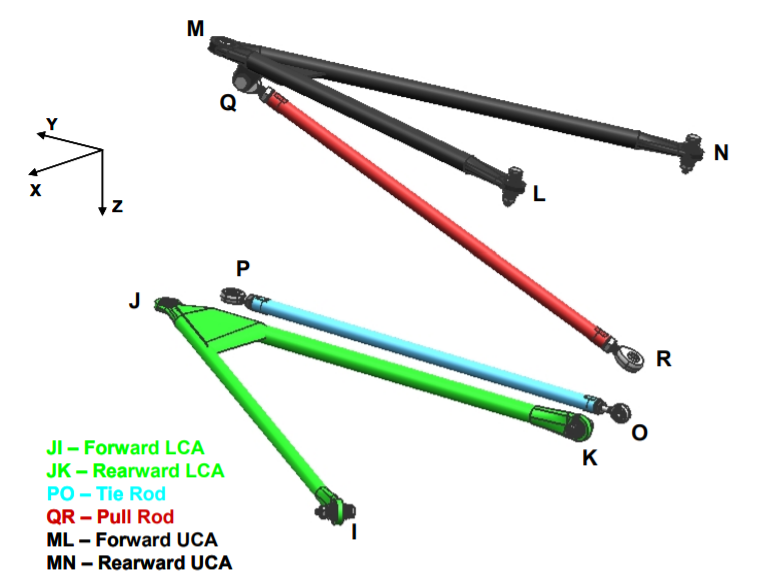

## Part 3: Vectors of Nodes and Their Magnitudes

% Right lower a-arm
JI = [J(1)-I(1) J(2)-I(2) J(3)-I(3)];
ji = sqrt( JI(1)^2 + JI(2)^2 + JI(3)^2);
Zji = JI/ji;


% Left lower a-arm
JK = [J(1)-K(1) J(2)-K(2) J(3)-K(3)];
jk = sqrt( JK(1)^2 + JK(2)^2 + JK(3)^2);
Zjk = JK/jk;


% Toe link
PO = [P(1)-O(1) P(2)-O(2) P(3)-O(3)];
po = sqrt( PO(1)^2 + PO(2)^2 + PO(3)^2);
Zpo = PO/po;


% Pull rod
QR = [Q(1)-R(1) Q(2)-R(2) Q(3)-R(3)];
qr = sqrt( QR(1)^2 + QR(2)^2 + QR(3)^2);
Zqr = QR/qr;

% Right uppper a-arm
ML = [M(1)-L(1) M(2)-L(2) M(3)-L(3)];
ml = sqrt( ML(1)^2 + ML(2)^2 + ML(3)^2);
Zml = ML/ml;

% Left upper a-arm
MN = [M(1)-N(1) M(2)-N(2) M(3)-N(3)];
mn = sqrt( MN(1)^2 + MN(2)^2 + MN(3)^2);
Zmn = MN/mn;

% r-Vector from Wheel Center to Points
rJ = J-WheelCenter;
rK = K-WheelCenter;
rM = M-WheelCenter;
rN = N-WheelCenter;
rP = P-WheelCenter;
rO = O-WheelCenter;
rQ = Q-WheelCenter;
rR = R-WheelCenter;


## Part 5: Solving for each case


% Matrix of the sum of forces in each coordinate direction
A = [Zji(1) Zjk(1) Zml(1) Zmn(1) Zpo(1) Zqr(1);...
     Zji(2) Zjk(2) Zml(2) Zmn(2) Zpo(2) Zqr(2);...
     Zji(3) Zjk(3) Zml(3) Zmn(3) Zpo(3) Zqr(3);...
    (Zji(3)*rJ(2)-Zji(2)*rJ(3)) (Zjk(3)*rJ(2)-Zjk(2)*rJ(3)) (Zml(3)*rM(2)-Zml(2)*rM(3)) (Zmn(3)*rM(2)-Zmn(2)*rM(3)) (Zpo(3)*rO(2)-Zpo(2)*rO(3)) (Zqr(3)*rQ(2)-Zqr(2)*rQ(3));...
    (Zji(3)*rJ(1)-Zji(1)*rJ(3)) (Zjk(3)*rJ(1)-Zjk(1)*rJ(3)) (Zml(3)*rM(1)-Zml(1)*rM(3)) (Zmn(3)*rM(1)-Zmn(1)*rM(3)) (Zpo(3)*rO(1)-Zpo(1)*rO(3)) (Zqr(3)*rQ(1)-Zqr(1)*rQ(3));...
    (Zji(2)*rJ(1)-Zji(1)*rJ(2)) (Zjk(2)*rJ(1)-Zjk(1)*rJ(2)) (Zml(2)*rM(1)-Zml(1)*rM(2)) (Zmn(2)*rM(1)-Zmn(1)*rM(2)) (Zpo(2)*rO(1)-Zpo(1)*rO(2)) (Zqr(2)*rQ(1)-Zqr(1)*rQ(2))];

% % Forces that were acting on the contact patch moved to the center of the
% % upright: their magnitude is the same as at the contact patch
% Fx = 0;
% Fy = -1802;
% Fz = -1135;
% 
% % Moments created on upright center from forces on contact patch (from
% % moment about upright center point)
% Mx = -12.7;
% My = 0;
% Mz = 457.8;

% Vector of forces
b = [Fx; Fy; Fz; Mx; My; Mz];

% solution vector: a vector of forces in each member
X = A\b;

% Renaming solution appropriately:
Fji = X(1);  % Force in front lower a-arm
Fjk = X(2);  % Force in rear lower a-arm
Fml = X(3);  % Force in front upper a-arm
Fmn = X(4);  % Force in rear upper a-arm
Fpo = X(5);  % Force in toe link
Fqr = X(6);  % Force in pull-rod

fprintf("The force in the front lower a-arm is %.1f Newtons\n", Fji)

The force in the front lower a-arm is 7049.1 Newtons


fprintf("\tFji = < %6.1f   %6.1f   %6.1f >",Fji.*Zji)

	Fji = < -3205.5   6276.9   -125.9 >

fprintf("The force in the rear lower a-arm is %.1f Newtons\n", Fjk)

The force in the rear lower a-arm is 8789.9 Newtons


fprintf("\tFjk = < %6.1f   %6.1f   %6.1f >",Fjk.*Zjk)

	Fjk = < 3997.1   7827.0    157.0 >

fprintf("The force in the front upper a-arm is %.1f Newtons\n", Fml)

The force in the front upper a-arm is -2688.5 Newtons


fprintf("\tFml = < %6.1f   %6.1f   %6.1f >",Fml.*Zml)

	Fml = < 1299.5   -2324.2   -370.7 >

fprintf("The force in the rear upper a-arm is %.1f Newtons\n", Fmn)

The force in the rear upper a-arm is -15645.0 Newtons


fprintf("\tFmn = < %6.1f   %6.1f   %6.1f >",Fmn.*Zmn)

	Fmn = < -6912.2   -13759.5   -2768.3 >

fprintf("The force in the toe link is %.1f Newtons\n", Fpo)

The force in the toe link is -7369.8 Newtons


fprintf("\tFpo = < %6.1f   %6.1f   %6.1f >",Fpo.*Zpo)

	Fpo = < 3351.3   -6562.4    131.7 >

fprintf("The force in the pull rod is %.1f Newtons\n", Fqr)

The force in the pull rod is 13505.2 Newtons


fprintf("\tFqr = < %6.1f   %6.1f   %6.1f >",Fqr.*Zqr)

	Fqr = < 4059.6   11132.2   6479.6 >

disp ("===========================================")

fprintf("The max case x Force is %.1f N\n", Fx)

The max case x Force is 2589.8 N


fprintf("The max case y Force is %.1f N\n", Fy)

The max case y Force is 2589.8 N


fprintf("The max case z Force is %.1f N\n", Fz)

The max case z Force is 3503.3 N


fprintf("The max case x moment is %.1f N-m\n", Mx)

The max case x moment is 657.8 N-m


fprintf("The max case y moment is %.1f N-m\n", My)

The max case y moment is 657.8 N-m


fprintf("The max case z moment is %.1f N-m\n", Mz)

The max case z moment is 249.9 N-m


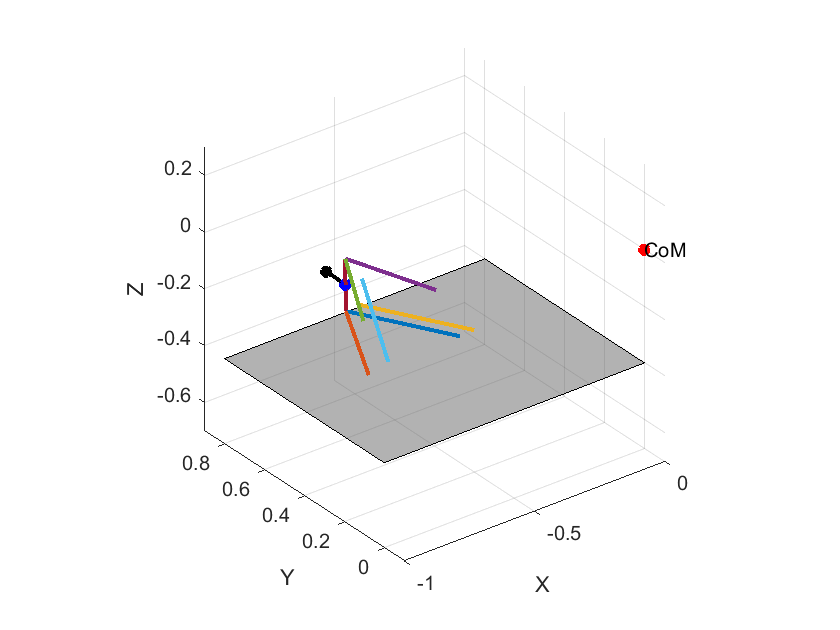


figure(1)
set(groot,'defaultLineLineWidth',2)
plot3([I(1) J(1)],[I(2) J(2)], [I(3) J(3)]);    % IJ
hold on
plot3([K(1) J(1)],[K(2) J(2)], [K(3) J(3)]);    % KJ
plot3([O(1) P(1)],[O(2) P(2)], [O(3) P(3)]);    % OP
plot3([L(1) M(1)],[L(2) M(2)], [L(3) M(3)]);    % LM
plot3([N(1) M(1)],[N(2) M(2)], [N(3) M(3)]);    % NM
plot3([Q(1) R(1)],[Q(2) R(2)], [Q(3) R(3)]);    % QR
plot3([J(1) M(1)],[J(2) M(2)], [J(3) M(3)]);    % JM
plot3(WheelCenter(1), WheelCenter(2), WheelCenter(3), 'k*');  %text(UprightCenter(1), UprightCenter(2), UprightCenter(3), "UC");
plot3(upright_center(1), upright_center(2), upright_center(3), 'b*');

plot3([WheelCenter(1) upright_center(1)], [WheelCenter(2) upright_center(2)], [WheelCenter(3), upright_center(3)], 'k');
plot3(0,0,0,'r*');  text(0,0,0,"CoM")

xpatch = [0 -1 -1 0]; ypatch = [0 0 .8 .8]; zpatch = [-h_cm -h_cm -h_cm -h_cm];
patch(xpatch, ypatch, zpatch, [.4, .4, .4])
alpha .5

xlabel X; ylabel Y; zlabel Z
xlim([-1,0])
axis vis3d
grid on
daspect([1 1 1])